# Reset

clear all;
close all;
clc;

# Black box estimation of wheel velocity transfer function

## Parameters

T_sample = 0.002; % Sample time [s]
t_start = 0.3; % Start mark of data we use for transfer function estimation [s]
t_step = 0.5; % time of step [s]

## Preprocessing

data = readtable('wheelsdown_blackbox.txt', 'CommentStyle', '%');
data(:,end) = []; % MATLAB produces an empty column on the end, we remove it here.

data.Properties.VariableNames = {'t' 'u_l' 'u_r' 'v_l' 'v_r'}; % Label the data, for convenience

data(data.t < t_start, :) = []; % Trim data

data = rmmissing(data);
data = rmoutliers(data, 'movmedian', 20);

% Offset time so data starts at t=0
data.t = data.t - t_start; 
t_step = t_step - t_start;
t_end = data.t(end);

% Offset measurements so the step starts in zero
data.u_l = data.u_l - mean(data.u_l(data.t < t_step));
data.u_r = data.u_r - mean(data.u_r(data.t < t_step));
data.v_l = data.v_l - mean(data.v_l(data.t < t_step));
data.v_r = data.v_r - mean(data.v_r(data.t < t_step));

% Try smoothing measurements to improve 
% data.v_l = smoothdata(data.v_l, 'gaussian', 10);

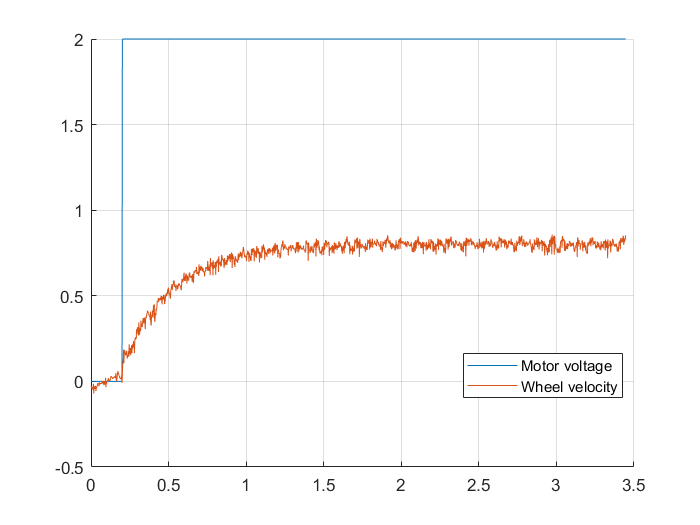

figure('Name', 'Wheels down step response, left wheel, processed');
hold on;
plot(data.t, data.u_l);
plot(data.t, data.v_l);
hold off;
grid on;
legend('Motor voltage', 'Wheel velocity', 'Location', 'best');

## Transfer function estimation

tfest_data = iddata(data.v_l, data.u_l, T_sample);

G_wv{1} = tfest(tfest_data, 2, 0);
G_wv{1}


ans =
 
  From input "u1" to output "y1":
         2836
  -------------------
  s^2 + 1951 s + 7093
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using TFEST on time domain data "tfest_data".
Fit to estimation data: 87.96%                         
FPE: 0.0007035, MSE: 0.0006992                         


% G_wv{2} = tfest(tfest_data, 2, 1);
% G_wv{2}
% G_wv{3} = tfest(tfest_data, 3, 0);
% G_wv{3}

## Step response simulation

step_opt = stepDataOptions('StepAmplitude', 2);
[y1, t1] = step(G_wv{1}, t_end - t_step, step_opt);
% [y2, t2] = step(G_wv{2}, t_end - t_step, step_opt);
% [y3, t3] = step(G_wv{3}, t_end - t_step, step_opt);

figure('Name', 'Simulated step response');
hold on;
plot(data.t - t_step, data.v_l);
plot(t1,y1);
% plot(t2,y2);
% plot(t3,y3);
xlim([0,t_end-t_step])
hold off;
grid on;
legend('Measured step response', '2p0z', '2p1z', '3p0z', 'Location', 'best');

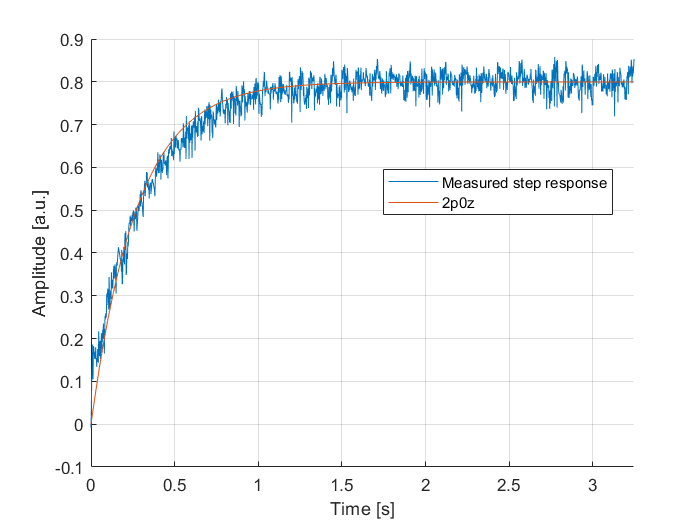

xlabel('Time [s]');
ylabel('Amplitude [a.u.]');

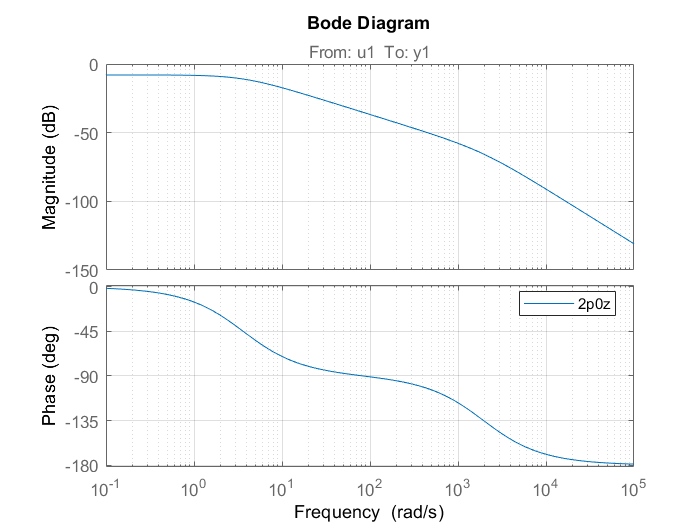

figure('Name', 'Bode plot of wheel velocity transfer function')
hold on;
bode(G_wv{1});
% bode(G_wv{2});
% bode(G_wv{3});
hold off;
grid on;
legend('2p0z', '2p1z', '3p0z', 'Location', 'best');


% figure('Name', 'Nyquist plot of wheel velocity transfer function')
% hold on;
% nyquist(G_wv{1});
% nyquist(G_wv{2});
% nyquist(G_wv{3});
% hold off;
% grid on;
% legend('2p0z', '2p1z', '3p0z', 'Location', 'best');

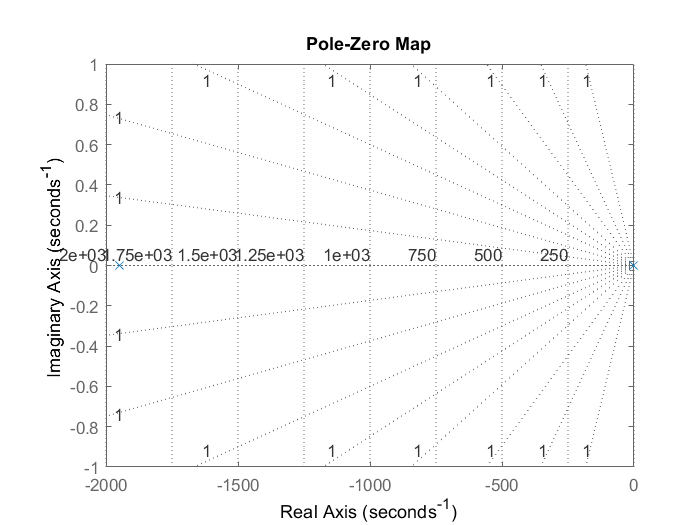

[num_wv, denom_wv] = tfdata(G_wv{1}, 'v');

figure;
pzmap(G_wv{1});
grid on;

# Designing a position controller

A controller is designed to control the position of the robot, using the above estimated transfer function as a model for the wheels. The controller should correct as fast as possible, with no overshoot.

A PI-Lead controller is chosen.

% Initial parameters are chosen
alpha = 0.1;
gamma_M = 60; % Phase margin [deg]
N_i = 3; % Ratio between system cross-over frequency and PI corner frequency

% Choose cross-over frequency
omega_c = 12; % [rad/s]

% phi_m = asin((1-alpha)/(1+alpha)) * 180/pi; % Max phase shift of lead compensator [deg]
% phi_PI = -atan(1/N_i) * 180/pi; % PI controller phase shift [deg]
% 
% % Compute phase at cross-over frequency
% phi_c = -180 + gamma_M - phi_m - phi_PI % [deg]

% Compute time constants
T_d = 1/(sqrt(alpha)*omega_c)

T_d = 0.2635

T_i = N_i/omega_c

T_i = 0.2500


C_d = tf([T_d, 1], [alpha*T_d, 1]);
C_i = tf([1],[T_i, 0]);

Determine proportional gain Kp:

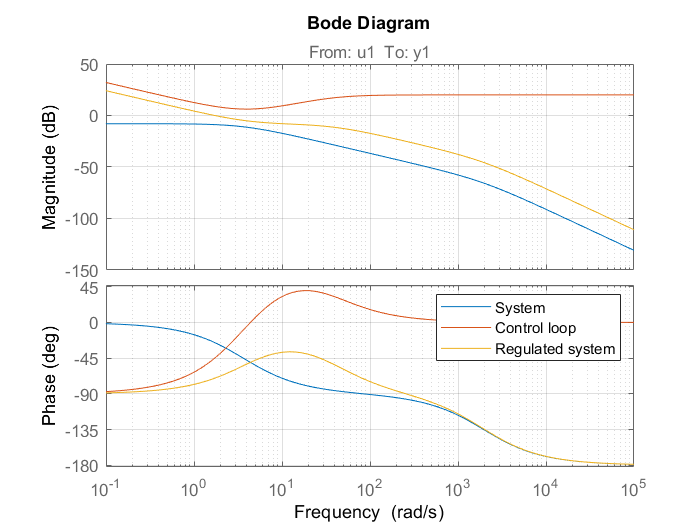

% Bode plot of PI-lead transfer function with unity proportional gain.
figure;
hold on;
bode(G_wv{1});
bode((1 + C_i) * C_d);
bode(G_wv{1} * (1 + C_i) * C_d);
hold off;
grid on;
legend('System', 'Control loop', 'Regulated system')

% From bode plot read how much the magnitude needs to be raised at omega_c
% becomes the c
dA_dB = 8.25;

Kp_wv = 10^(dA_dB/20)

Kp_wv = 2.5852

% Increase Kp a bit because we can, and it reduces both rise time and overshoot :)
Kp_wv = Kp_wv * 3

Kp_wv = 7.7557

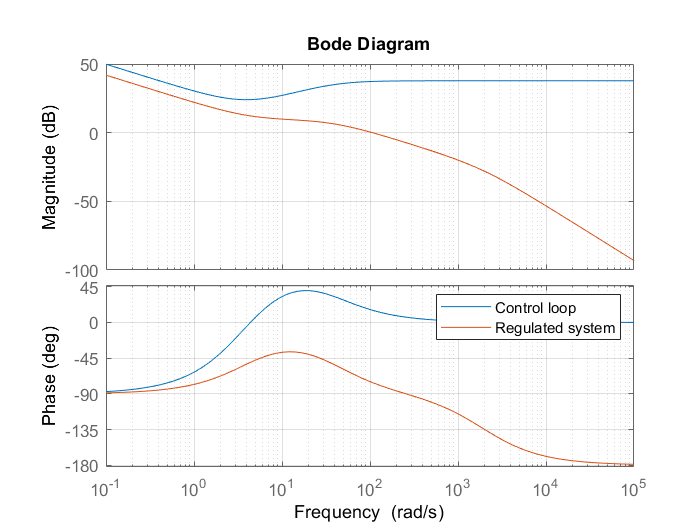

C_wv = Kp_wv * (1 + C_i) * C_d;
figure;
hold on;
bode(C_wv);
bode(G_wv{1}*C_wv);
hold off;
grid on;
legend('Control loop', 'Regulated system');

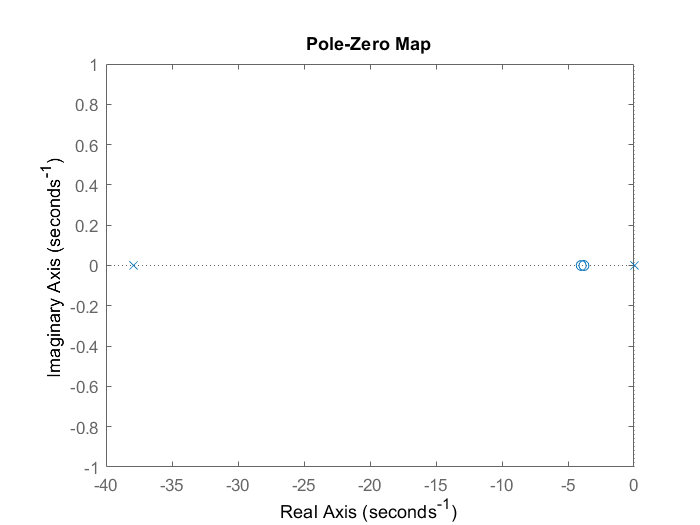

figure;
pzmap(C_wv)